#  Optical Flow

[⇦ Main Menu](matlab:open('..\..\deep-learning-for-image-processing\MainMenu.mlx'))

Introductory information including applications giving reasons to care about the material.

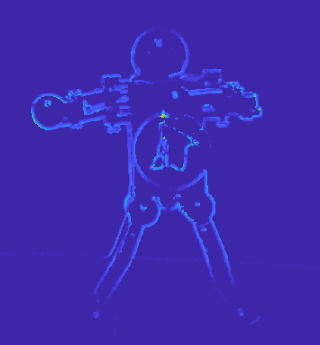

One sentence summary of the content 

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Overview of Optical Flow Techniques

The goal of optical flow is to recover the motion of each pixel in an image. Optical flow measures the movement of brightness patterns in images, which is useful for analyzing two consecutive frames to estimate pixel motion. It describes the direction and speed of motion of features within an image.

By tracking brightness patterns from one image to the next, optical flow estimates the movement of each pixel between two time points, we can estimate the motion or the brightness between one image at $I(x,y,t) $ and the subsequent image at $I(x,y,t+\delta{t})$. So we are following pixels from one time point to a second time point at $t= t+\delta{t}$.

There are two assumptions that help us calculate optical flow. 

**Assumption 1**. Brightness Constancy which assumes brightness is the same for a pixel as it moves through time.

**Assumption 2**. Small motion which allows us to linearize the brightness constancy constraint. 

### Assumption 1. Brightness Constancy

As you vary $t$, as a point moves, its brightness remains the same. This is given by:

 
$$I(x(t),y(t),t)= Constant$$


Let's say we have a scene point moving through an image sequence of length, $k$ given by. For $ (x(1),y(1))$ until $ (x(k),y(k))$, the intensity (or brightness) of this point is the same for all frames. 

  **Try**. Visualize assumption 1 to calculate the intensity of the point $ (x(k),y(k))$ for the frames of length $k$.Track the five points from scene to scene. Does the pixel intensity remain constant?

numFrames= 3;
[intensityHistory,pixelCoords] = generateScatterPlot(numFrames,true,false);

DispIntens(pixelCoords,intensityHistory);

### Assumption 2. Small Motion

$I(x,y,t) $, if we follow pixel $(x,y)$ that is traveling at velocity, or optical flow of $(u,v)$ from one frame to another at time step, $\delta{t}$, in the consecutive frame,$I(x,y,t+\delta{t})$, the pixel's new coordinates are $(x + u\delta{t}, y+v\delta{t})$, where the displacements are given by: $\delta{x},\delta{y})=(u\delta{t},v\delta{t})$.

  **Try**. Visualize the motion of pixels traveling from one frame to another.

 
x1 = -10+2*rand(1,1); % Generate a random x coordinate between -10 and 10
y1 = -10+2*rand(1,1); % Generate a random y coordinate between -10 and 10

figure
tiledlayout(1,2)
nexttile
scatter(x1,y1,"filled",SeriesIndex=1)
text(x1,y1,"($x,y$)",Interpreter="latex",FontSize=14,Position=[x1-0.5 y1-0.5],VerticalAlignment="top",HorizontalAlignment="right");
delta = 10; % Define a small delta for movement
x2 = x1+delta;
y2 = y1+delta;

hold on
scatter(x2,y2,"filled")
quiver(x1,y1,(x2-x1),(y2-y1),1,LineWidth=1.5,MaxHeadSize=1,AutoScale="on"); % Include quiver vectors for the original points
hold off

text(x2,y2,"($x+u\delta{t},y+u\delta{t}$)",Interpreter="latex",FontSize=14,Position=[x2+0.5 y2+0.5],VerticalAlignment="bottom",HorizontalAlignment="center");

% Set axis properties
title("I(x,y,t)",FontSize=14)
xticks([])
yticks([])
axis padded
ax1 = gca;
ax1.Box = "on";
ax1.XLim = [-20,20];
ax1.YLim = [-20,20];
nexttile
scatter(x2,y2,"filled")

% Set axis properties
title("I(x,y,t+\delta{t})",FontSize=14)
xticks([])
yticks([])
axis padded
ax2 = gca;
ax2.Box = 'on';
ax2.XLim = [-100,100];
ax2.YLim = [-100,100];

 If we assume that the distance a pixel travels in time $\delta{t}$ is small, then $ t + \delta{t}$ is equivalently, $t$. Therefore for a really small space-time step, the brightness of the image point remains constant over time as shown in this equation: 


$$\text {Brightness of Pixel: } (x+u\delta{t},y+v\delta{t},t+\delta{t} = I(x,y,t)$$


## Brightness Constancy Equation

With the two assumptions, for a small space and small time step, we have an equivalent brightness between two consecutive frames. This gives us the Brightness Constancy Equation.

$\frac{dI}{dt}=\frac{\partial I}{\partial x} \frac{dI}{dx} + \frac{\partial I}{\partial y} {\partial y} \frac{dI}{dx} + \frac{\partial I}{\partial t} = 0$  simplifies to  $$I_xu+I_yv+I_t=0$$

where $I_x$ and $I_y$ represent the gradient of image brightness, $I_t$ represents the temporal gradient, and $u$ and $v$represent the optical flow velocity. In this equation, the unknowns are $u$ and $v$.  If we bring this equation into the vector form, we can more easily see that we have own equation and two unknowns giving an unconstrained equation.


$$\nabla{I}\cdot[u,v]^T+I_t=0$$


There are a few different approaches to providing the additional constraint to make the Brightness Constancy equation solvable including the Lucas-Kanade method, Horn-Schunk Method, and the Lucas-Kanade Derviative of Gaussian Method.

## Lucas-Kanade Method

### Assumption 3. Spatial Coherence.

The Lucas-Kanade method for optical flow estimation relies on the assumption of spatial coherence. This means that within a small patch of the image, all points are assumed to move similarly, sharing a single velocity. Essentially, we assume that neighboring pixels within this patch have the same motion vector, allowing us to estimate the optical flow more accurately by considering the collective movement of pixels. The Lucas-Kanade approach produces a sparse flow field because it computes flow in places where the horizontal and or vertical gradients have clear differences. If we have edges and corners, the Lucas-Kanade method works well. 

  **Try**. Visualize the small patch moving at one velocity.

 
figure
tiledlayout(1,2)

nexttile
title("$I(x,y,t)$",Interpreter="latex",FontSize=14)
% Set up axes
ax5 = gca;
xticks([])
yticks([])
ax5.XLim = [0,100];
ax5.YLim = [0,100];
ax5.Box ="on";
xLimits = ax5.XLim;
yLimits = ax5.YLim;

% Randomly generate a rectangle with width and height equal to 5
xPos = randi([0,95]); % Ensure the rectangle fits within the limits
yPos = randi([0,95]);
r = rectangle(EdgeColor="red",LineWidth=2,Position=[xPos,yPos,5,5]);
hold on

% Define a new random endpoint within the axis limits
newXPos = randi([0,95]);
newYPos = randi([0,95]);
% Define the start and end points of the quiver vector
startPoint = [r.Position(1)+r.Position(3)/2,r.Position(2)+r.Position(4)/2]; % Center of the original rectangle
endPoint = [newXPos+2.5,newYPos+2.5]; % Center of the new rectangle

% Calculate the direction and length of the vector
vector = endPoint-startPoint;

% Add quiver vector to the plot
quiver(startPoint(1),startPoint(2),vector(1),vector(2),0, Color="blue",LineWidth=1,MaxHeadSize=1);
rnew = rectangle(ax5,EdgeColor="red",LineWidth=2,Linestyle=":",Position=[newXPos,newYPos,5,5]);
hold off

nexttile
% Move rectangle to a new position
title("$I(x,y,t+\delta{T})$",Interpreter="latex",FontSize=14)
ax6 = gca;
xticks([])
yticks([])
ax6.XLim = [0,100];
ax6.YLim = [0,100];
ax6.Box ="on";

% Draw the second rectangle in the second tile
rnew = rectangle(ax6,EdgeColor=[0.3010,0.7450,0.9330],LineWidth=2,Position=[newXPos,newYPos,5,5]);

In this next demonstration, we will observe a small patch defined by a red square. This 1 x 1 blue square contains hundreds of pixels. Unlike assumption 1, where the points move in random directions, all the points within this red square move in the same direction. When we zoom in on the blue box, we can see that all the pixels are moving uniformly in the same direction.

  **Try**. Observe the pixels in the small patch moving at the same velocity.

numFramesB=4;
[intensityHistory,pixelCoords] = generateScatterPlot(numFrames,false,true);

** Application. **Use the Lucas-Kanade method to track the motion of a flower.

LKVid = VideoReader("Flower.mov",CurrentTime=0);
opticflowLK = opticalFlowLK;
DispOptFlow(LKVid,opticflowLK);

## Horn-Schunk Method

The Horn-Schunck method for optical flow estimation introduces a global smoothness constraint. This method assumes that the optical flow vectors change gradually from one pixel to the next, ensuring smooth transitions. Instead of assuming that a small patch of points moves similarly and shares a single velocity, the Horn-Schunck method assumes that neighboring pixels within a small window move in similar ways. By minimizing variations in flow, the Horn-Schunck method aims to produce a more coherent and smooth optical flow field.

Unlike the Lucas-Kanade method, which estimates optical flow locally within small neighborhoods, the Horn-Schunck method estimates optical flow across the entire image. It assumes that the flow field is smooth and changes gradually from one pixel to the next. Consequently, this method is more sensitive to noise but produces a denser flow field.

** Application. **Use the Lucas-Kanade method to track the motion of a car.

HSVid = VideoReader("CarB.mov",CurrentTime=0);
opticflowHS = opticalFlowHS;

DispOptFlow(HSVid,opticflowHS);

## Large Motion: Coarse-to-Fine Estimation

What if the small motion assumption does not hold? Imagine, you are taking a video with your phone, and you are not using using a tripod. Now, your camera is moving and your video is unstable and so now we have a case where there assumption 2 no longer holds. 

We can force the $\delta{x}$, and $\delta{y}$ to be small by using a resolution pyramid. " AT some point all resolutions will become less than a pixel in magnitude which will then make the small motion assumption 1 valid again. This resolution decreasing process blurs the image. 

  **Try**. Adjust the image resolution to blur the pixels to compute lower resolution images.  

n = 30;
Na = 6;
ChosenVid = "FlowerB.mov";
FlowerVid = VideoReader(ChosenVid); % Create a video reader object
frameNumb = FlowerVid.NumFrames;
firstFrame = read(FlowerVid,n);
secondFrame = read(FlowerVid,n+1); % Read the second frame

T = im2double(firstFrame); % Convert the first frame to double for processing
TplusdelT = im2double(secondFrame); % Convert the second frame to double for processing

figure
tiledlayout(2,2,TileSpacing="none",Padding="tight") % Set up tiled layout

nexttile % Tile (1,1)
imshow(T)  % t at resolution original

nexttile % Tile (1,2)
ResPyr(Na,firstFrame,1)

nexttile % Tile (2,1)
imshow(TplusdelT) % t + delta t at resolution original

nexttile % Tile (2,2)
ResPyr(Na,secondFrame,1)
imgTplus = secondFrame;

## Lucas-Kanade derivative of Gaussian Method

In the previous section you decreased the image resolution to force the validity of assumption 1. The Lucas-Kaand

  **Try**.

LKDoGVid = VideoReader("FlowerB.mov",CurrentTime=0);
opticflowLKDoG = opticalFlowLKDoG;
DispOptFlow(LKDoGVid,opticflowLKDoG);

## Compare Optical Flow Methods

  **Try**.

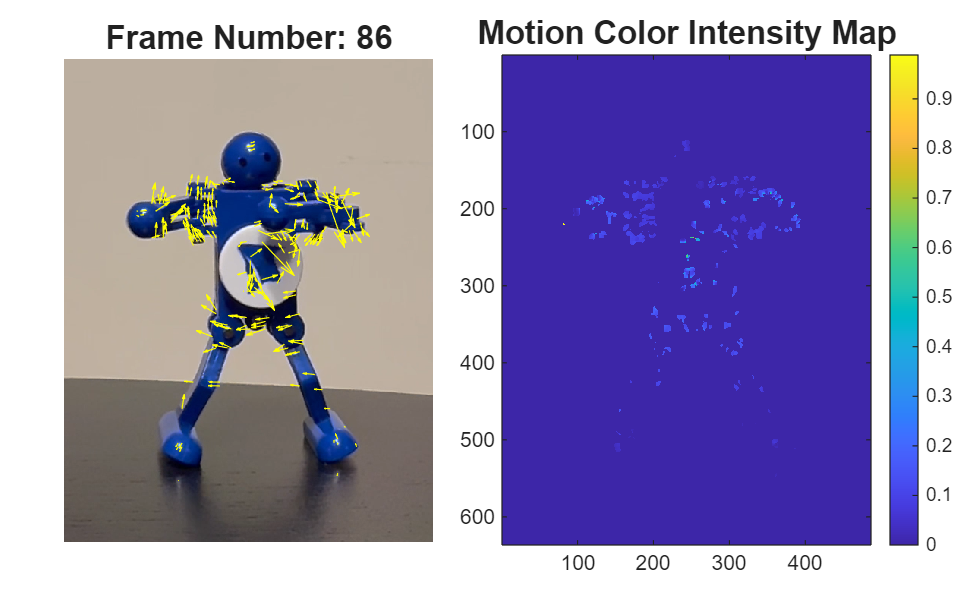

CompVid = VideoReader("RobotB.mov",CurrentTime=0);
opticflow =opticalFlowLKDoG;
DispOptFlow(CompVid,opticflow);

#### Subsubsection Name

**Usual pictograms.**

 **Exercise.**

  **Try**.

  **Pro-tip**.

 **Pro-tip.**

** Demonstration**.

 **Reflect**.

** Application.**

**Different pictograms **can be found on this [page](https://web-standards.mathworks.com/image-based-content/pictograms/), and the file can be found on this [one](https://mathworks.sharepoint.com/sites/emktg_creative_ext/Resources/Forms/AllItems.aspx?csf=1&web=1&e=5tEMMy&cid=40125015%2D41c9%2D437b%2Da62e%2D75ac09bf9746&RootFolder=%2Fsites%2Femktg%5Fcreative%5Fext%2FResources%2Ficons%2Ficon%2Dfont%2Ffiles%2Fsvgs&FolderCTID=0x012000304F6D27DE3DBB4FA35AA560DE4A0D89).

## Further Exploration

[⇦ Return to the main menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function [px,py,intensity] = ScatPlot(x,k,y,fixedColor)
colormap("parula");
colorbar

% Convert scatter plot to an image
frame = getframe(gca); % Capture figure as image
img = frame.cdata; % Extract image data

% Define points of interest
px = x(k);
py = y(k);

% Convert plot coordinates to pixel indices
ax = gca;
xticks([]);
yticks([]);
ax.XLim = [0,100];
ax.YLim = [0,100];
ax.Box ="on";

% Extract pixel intensity (we use the fixed color as the intensity)
intensity = fixedColor(k); % Use the fixed color intensity for the point 
end


function [intensityHistory, pixelCoords] = generateScatterPlot(numFrames,useRandomDelta,addRectangle)
% Generate initial scatter plot data
x = 20 + rand(5,1)*60; % Initial X-coordinates
y = 20 + rand(5,1)*60; % Initial Y-coordinates
c = rand(5,1); % Intensity values (color data)

% Fix the color values (so each point keeps the same color)
fixedColor = c; % Fixed color for each point

prevX = x;
prevY = y;

% Initialize arrays to store intensity values for each pixel across frames
intensityHistory = zeros(5,numFrames); % 5 points, numFrames
pixelCoords = zeros(5,2,numFrames); % Store x and y pixel coordinates for each point
pixelCoords = round(pixelCoords,2,"significant");

figure
tiledlayout(1,2)

% Loop through frames
for k = 1:numFrames
           DelT = rand(5,1)*20; % Random delta for movement
   
    % Update positions
    xNext = x+DelT;
    yNext = y+DelT;

    % Ensure points remain within bounds [0, 100]
    xNext = max(20,min(80,xNext));
    yNext = max(20,min(80,yNext));

    % Plot current frame
    nexttile(1)
    scatter(x,y,50,fixedColor,"filled");
    title("I(x,y,k=" + num2str(k) + ")",FontSize=14)
    hold on
    % Draw quiver plot showing movement from previous to current frame
    if ~useRandomDelta
        % Use a small delta to show movement even if it's uniform
        smallDelta = 0.1; 
        quiver(x,y,smallDelta*ones(size(prevX)),smallDelta*ones(size(prevY)),0.4,LineWidth=1.5,Color="black",MaxHeadSize=1,AutoScale="on");
    else
        quiver(x,y,(xNext-x),(yNext-y),0.4,LineWidth=1.5,Color="black",MaxHeadSize=1,AutoScale="on");
    end

    if addRectangle
        rectangle(Position=[0,0,100,100],EdgeColor=[0.3010,0.7450,0.9330],LineWidth=2);
    end
    hold off

    % Capture scatter plot intensity using ScatPlot and store intensity for each point
    for i = 1:length(x)
        [px,py,intensity] = ScatPlot(x,i,y,fixedColor); % Capture intensity for point i
        intensity = round(intensity,2,"significant");
        % Store the intensity for each point in the history
        intensityHistory(i,k) = intensity;
        px = round(px,2,"significant");
        py = round(py,2,"significant");
        pixelCoords(i,:,k) = [px,py]; % Store pixel coordinates
    end

    % Plot next frame
    nexttile(2)
    scatter(xNext,yNext,50,fixedColor,"filled");
    if addRectangle
        rectangle(Position=[0,0,100,100],EdgeColor="red",LineWidth=2);
    end
    title("I(x,y,k=" + num2str(k+1) + ")",FontSize=14)
    colorbar

    ax2 = gca;
    xticks([]);
    yticks([]);
    ax2.XLim = [0,100];
    ax2.YLim = [0,100];
    ax2.Box ="on";
    xLimits2 = ax2.XLim;
    yLimits2 = ax2.YLim;

    % Update for next iteration
    x = xNext;
    y = yNext;

    % Pause to visualize frames like an animation
    pause(2);
end
end



function DispIntens(pixelCoords,intensityHistory)
% Get the number of points and frames
numPoints = size(pixelCoords,1);
numFrames = size(intensityHistory,2);

% Initialize the data for the table
tableData = cell(numPoints,numFrames+2); % +2 for X, Y, and intensity columns

% Populate the table data
for i = 1:numPoints
    % Assign the pixel coordinates (X, Y) in the first two columns
    tableData{i,1} = pixelCoords(i,1,1); % X coordinate
    tableData{i,2} = pixelCoords(i,2,1); % Y coordinate

    % Assign the intensity values for each frame in the subsequent columns
    for k = 1:numFrames
        tableData{i,k+2} = intensityHistory(i,k); % Intensity value for each point at each frame
    end
end

% Define the column names for the table
columnNames = [{"X","Y"},strcat("Intensity at k = "+string(1:numFrames))];

% Convert the cell array to a table
intensityTable = cell2table(tableData,VariableNames=columnNames);

% Display the table
disp(intensityTable);
end

function ResPyr(N,firstImg,DrwLine)

for i = 1:N % loop to continue the pattern
    scaleFactor = 0.5^i; % Calculate the resizing factor directly
    imgAT = imresize(firstImg,scaleFactor);
    resizedImgT = imresize(imgAT,1/scaleFactor); % Resize to original size

    imshow(resizedImgT)
        title("Resolution of "+num2str(i),SeriesIndex=3)
   if DrwLine 
    hold on
    % Draw a vertical line 3/4 of the way down the image
    line([size(resizedImgT,2)*3/4,size(resizedImgT,2)*3/4], [1,size(resizedImgT,1)],SeriesIndex=6,LineWidth=2);
    hold off
   else
   end

end
end

function DispOptFlow(vidReader2,opticflow) % Function to display optical flow video along with color motion map
if ~strcmp(vidReader2,"Select") || ~strcmp(opticflow,"Select")
    figure;
    t = tiledlayout(1,2,TileSpacing="Compact",Padding="Compact");

    ax10 = nexttile;

    % Second tile for motion intensity map
    ax20 = nexttile;

    while hasFrame(vidReader2)
        frameRGB = readFrame(vidReader2);
        frameGray = im2gray(frameRGB);
        flow = estimateFlow(opticflow,frameGray);
        axes(ax10)
        imshow(frameRGB)

        hold on
        frameNumber = vidReader2.CurrentTime*vidReader2.FrameRate; % Calculate the current frame number
        frameNumber = round(frameNumber);
        title("Frame Number: "+num2str(frameNumber),FontSize=14); % Set the title with the frame number
        plot(flow,DecimationFactor=[5,5],Color="yellow",ScaleFactor=10);
        hold off

        drawnow

        axes(ax20)
        imagesc(flow.Magnitude)
        title("Motion Color Intensity Map",FontSize=14)
        colorbar
        pause(10^-3)
    end
else
    warning("Select a valid option.")
end
end